bode_plot_options = bodeoptions();
bode_plot_options.Grid = 'on';
%bode_plot_options.PhaseWrapping = 'on';

# Plant

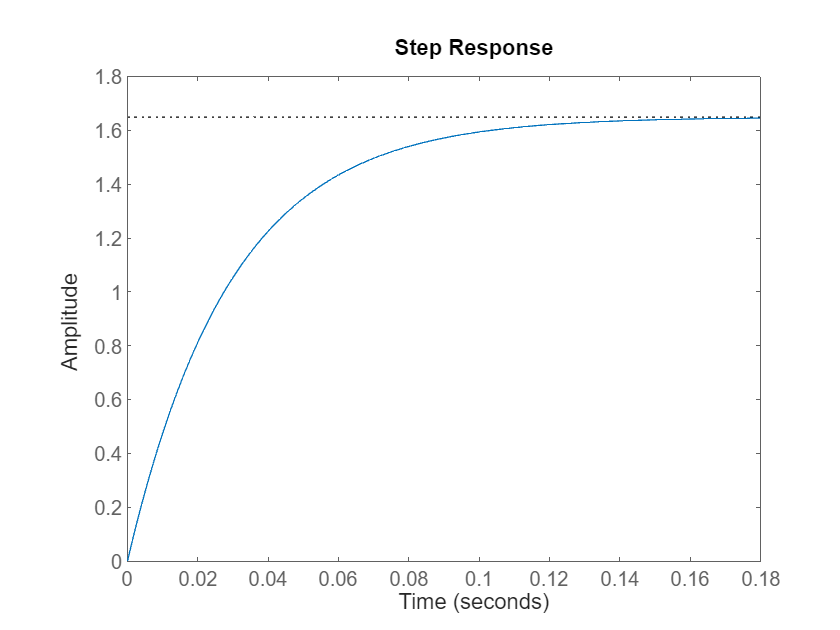

s = tf('s');
plant_tf = 55.99/(s+33.95);
step_response_parameters = stepinfo(plant_tf);
plant_ts = step_response_parameters.RiseTime;
step(plant_tf);

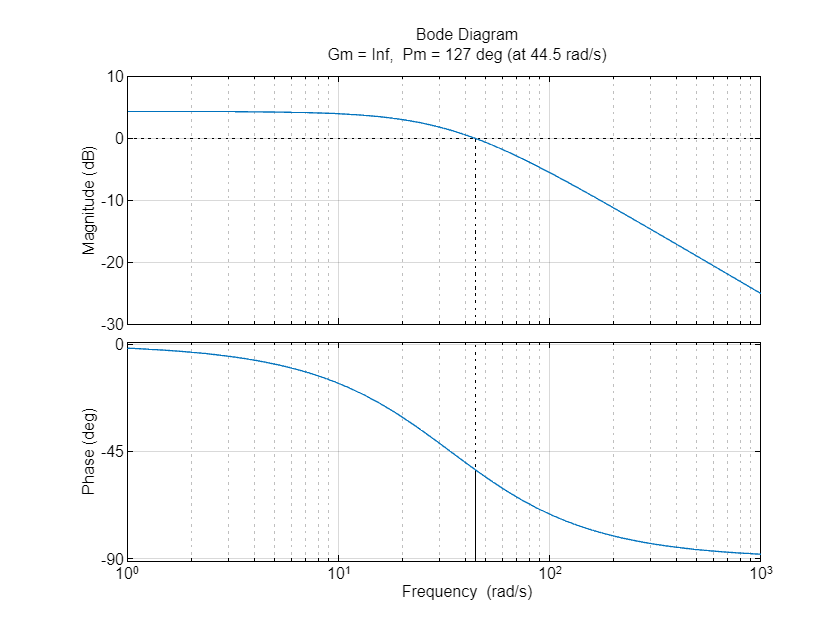

margin(plant_tf,bode_plot_options);

# Control Design

#### Parameters

Overshoot [Mp] <= 25%, Velocity Error [Ev] = 0, Pm >= 40°, Gm>=10dB

Controller type: 2 integrators and 2 lead compensators

## Integrators

2 integrators are assigned to get Ev=0, K is set to lower the negative phase margin and allow the lead compensators to fix the inestability created by the double integrators,

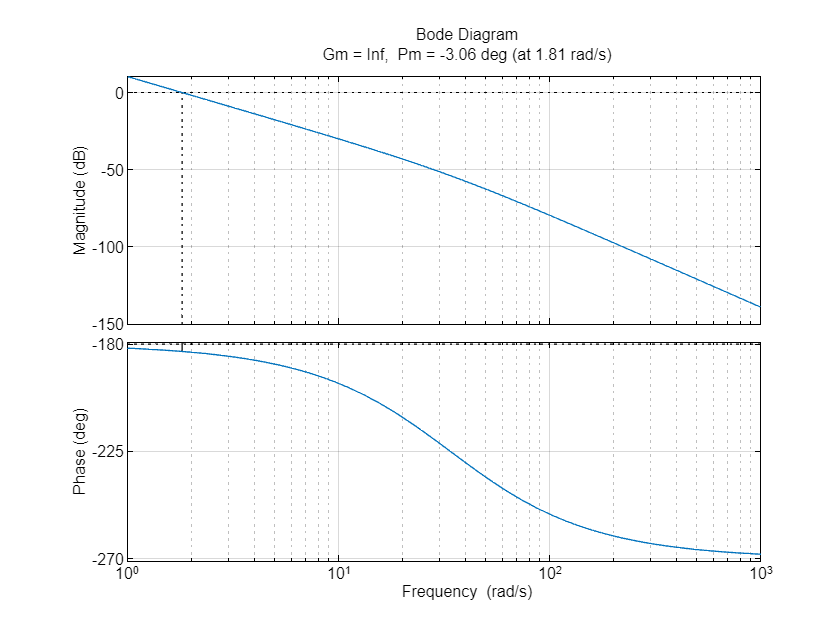

s = tf('s');
k =2;
integ_ctrl_tf = k/((s)^2);
integ_ctrl_plant_tf = series(integ_ctrl_tf,plant_tf);
margin(integ_ctrl_plant_tf,bode_plot_options);

## First Lead Compensator

required_pm1 = 40+35-(-3.06);
b_1 = (1 + sind(required_pm1))/(1-sind(required_pm1));
disp("w1_crossover_gain: " + num2str(-10*log(b_1)));

w1_crossover_gain: -45.157


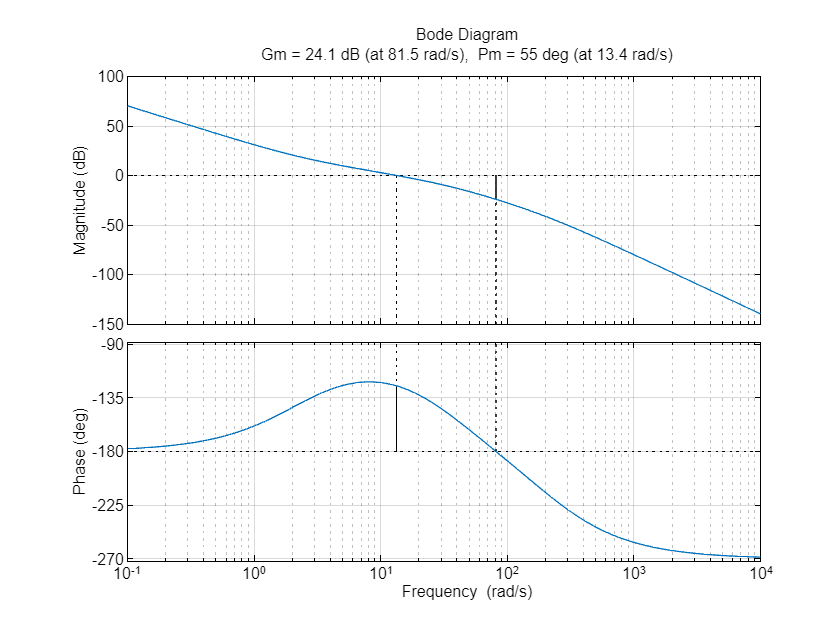

w1_crossover = 22.22;
T2_1=1/(sqrt(b_1)*w1_crossover);
k1 =10;
lead_ctrl_tf = k1*(1+(b_1*T2_1*s))/(1+(T2_1*s));
margin(lead_ctrl_tf*integ_ctrl_plant_tf,bode_plot_options);

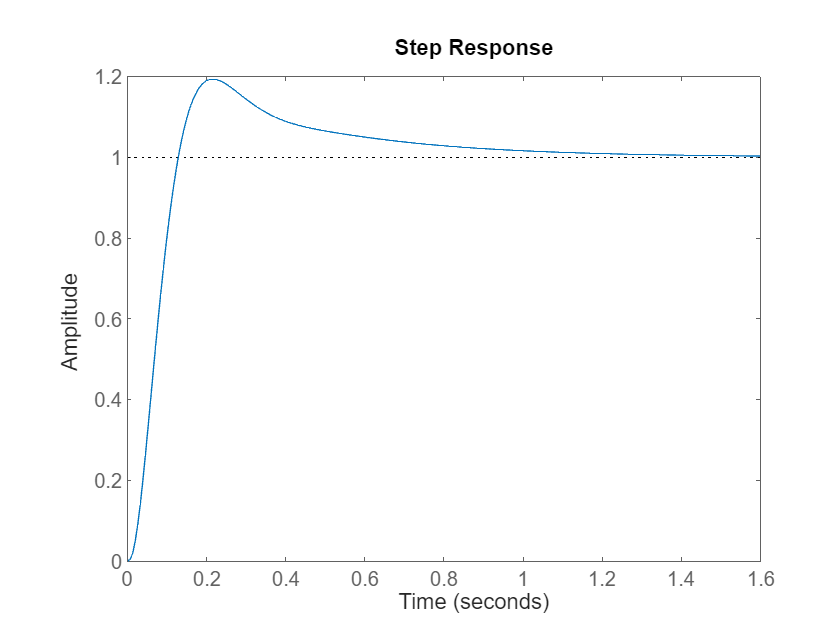

step(feedback(lead_ctrl_tf*integ_ctrl_plant_tf,1));

disp(stepinfo(feedback(lead_ctrl_tf*integ_ctrl_plant_tf,1)));

         RiseTime: 0.0853
    TransientTime: 0.9238
     SettlingTime: 0.9238
      SettlingMin: 0.9266
      SettlingMax: 1.1933
        Overshoot: 19.3347
       Undershoot: 0
             Peak: 1.1933
         PeakTime: 0.2132



## Discretization

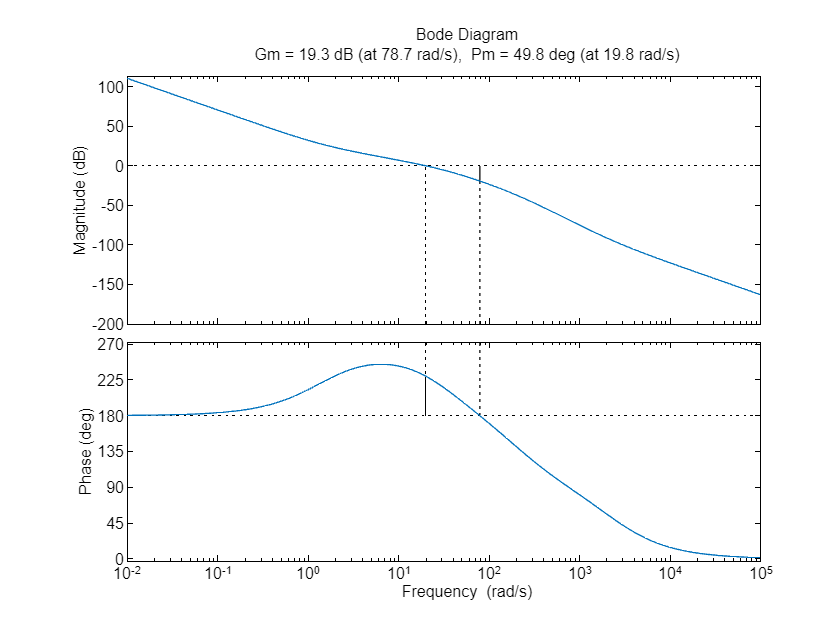

Ts = 0.005;
lead_ctrl_tf_z = c2d(lead_ctrl_tf,Ts,'zoh');
integ_ctrl_tf_z = c2d(integ_ctrl_tf,Ts,'zoh');
margin(d2c(lead_ctrl_tf_z*integ_ctrl_tf_z,'zoh')*plant_tf,bodeoptions);

#### Step response of Closed Loop Fully Controlled  

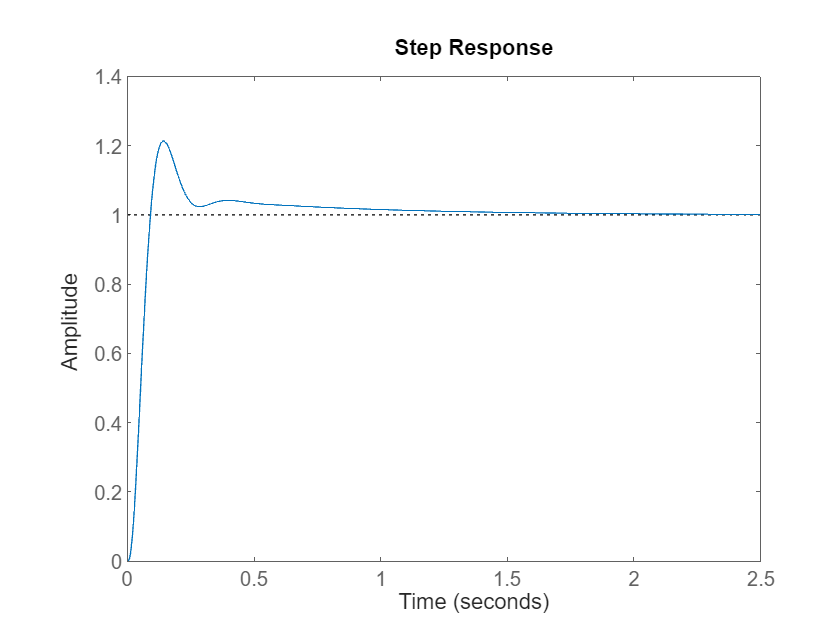

step(feedback(d2c(lead_ctrl_tf_z*integ_ctrl_tf_z,'zoh')*plant_tf,1));

disp(stepinfo(feedback(d2c(lead_ctrl_tf_z*integ_ctrl_tf_z,'zoh')*plant_tf,1)));

         RiseTime: 0.0589
    TransientTime: 0.8362
     SettlingTime: 0.8362
      SettlingMin: 0.9169
      SettlingMax: 1.2138
        Overshoot: 21.3829
       Undershoot: 0
             Peak: 1.2138
         PeakTime: 0.1420



# Final Controllers

## Double Integrator

[integ_ctrl_num,integ_ctrl_den] = tfdata(zpk(integ_ctrl_tf_z));
integ_ctrl_tf_z_neg = tf(cell2mat(integ_ctrl_num),cell2mat(integ_ctrl_den),Ts,"variable",'z^-1')

integ_ctrl_tf_z_neg =
 
  2.5e-05 z^-1 + 2.5e-05 z^-2
  ---------------------------
       1 - 2 z^-1 + z^-2
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


## Lead Compensator

[lead_ctrl_num,lead_ctrl_den]=tfdata(zpk(lead_ctrl_tf_z));
lead_ctrl_tf_z_neg = tf(cell2mat(lead_ctrl_num),cell2mat(lead_ctrl_den),Ts,"variable",'z^-1')

lead_ctrl_tf_z_neg =
 
  914.4 - 907.9 z^-1
  ------------------
   1 - 0.3456 z^-1
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


## Equivalent Controller


final_ctrl_tf_z = lead_ctrl_tf_z*integ_ctrl_tf_z;
[num,den] = tfdata(zpk(final_ctrl_tf_z));
final_ctrl_tf_neg_z = tf(cell2mat(num),cell2mat(den),Ts,"variable",'z^-1')

final_ctrl_tf_neg_z =
 
  0.02286 z^-1 + 0.0001636 z^-2 - 0.0227 z^-3
  -------------------------------------------
   1 - 2.346 z^-1 + 1.691 z^-2 - 0.3456 z^-3
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


final_ctrl_num = cell2mat(final_ctrl_tf_neg_z.Numerator);
final_ctrl_den= cell2mat(final_ctrl_tf_neg_z.Denominator);